clc
clear screen
close all

## Plotting the traces of the planes

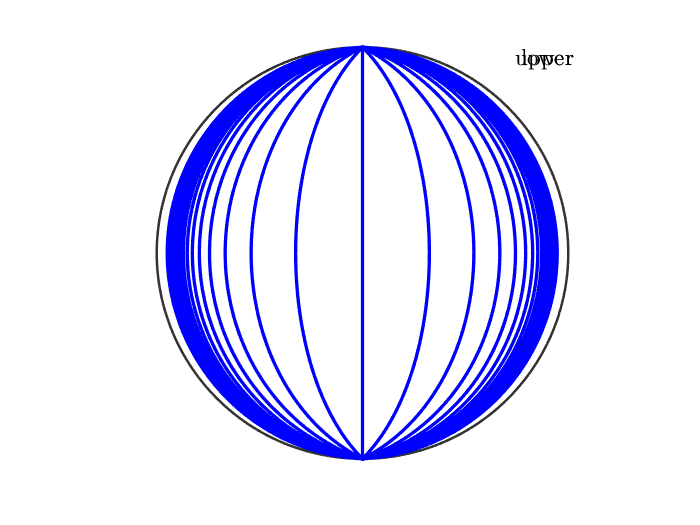

crys_symm=crystalSymmetry('432');
M=Miller(1,0,0,crys_symm);
figure
plot(M,'plane','linecolor','r','linewidth',2)
hold all
startValue = -10;
increment = .5;

% Define the number of iterations
numIterations = 40;

% Initialize the second variable
x = startValue;
% Loop over the specified number of iterations
for i = 1:numIterations
N=Miller(1,0,x,crys_symm);
x = x + increment;
plot(N,'plane','linecolor','b','linewidth',2)
hold off
end

## 1. ORIENTATION A (110)[1-12]

crys_symm=crystalSymmetry('432');

## Define orientation using Miller indices

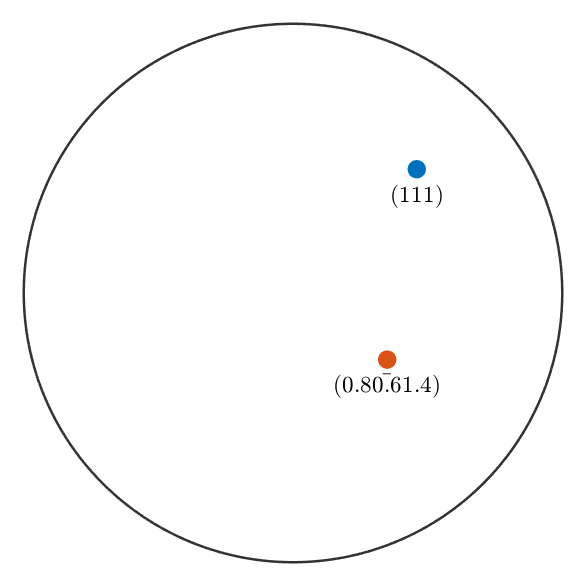

n=Miller(1,1,0,'hkl',crys_symm); % plane normal || ND
b=Miller(1,-1,2,'uvw',crys_symm); % rolling direction || RD
ori=orientation.byMiller(n,b);
%%(111) pole figure
m=Miller(1,1,1,crys_symm);
m1=ori*m;
m11=Miller(m1.x,m1.y,m1.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(m,'upper','labeled')
hold on
plot(m11,'upper','labeled')
hold off

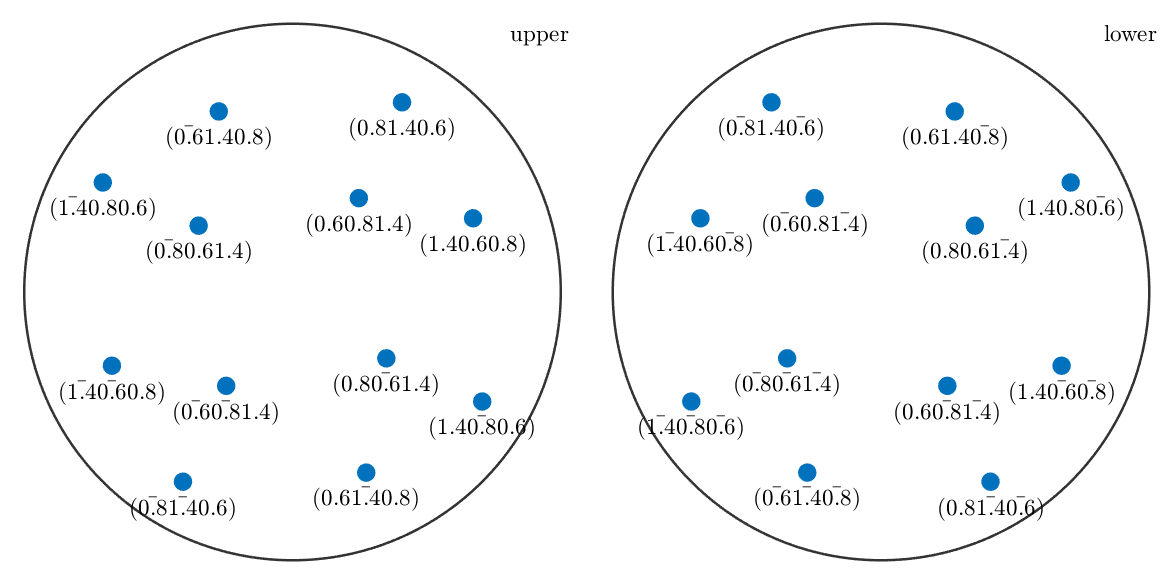



figure
m11=Miller(m1.x,m1.y,m1.z,crys_symm);
plot(m11.symmetrise,'labeled')

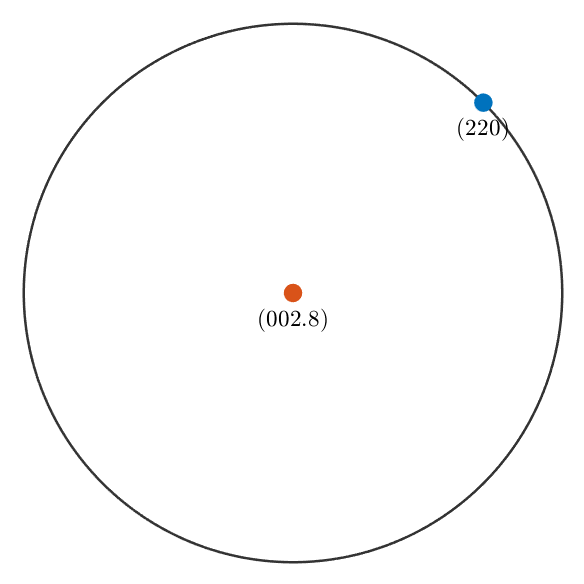


%%(220) pole figure
l=Miller(2,2,0,crys_symm);
l1=ori*l;
l11=Miller(l1.x,l1.y,l1.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(l,'upper','labeled')
hold on
plot(l11,'upper','labeled')
hold off

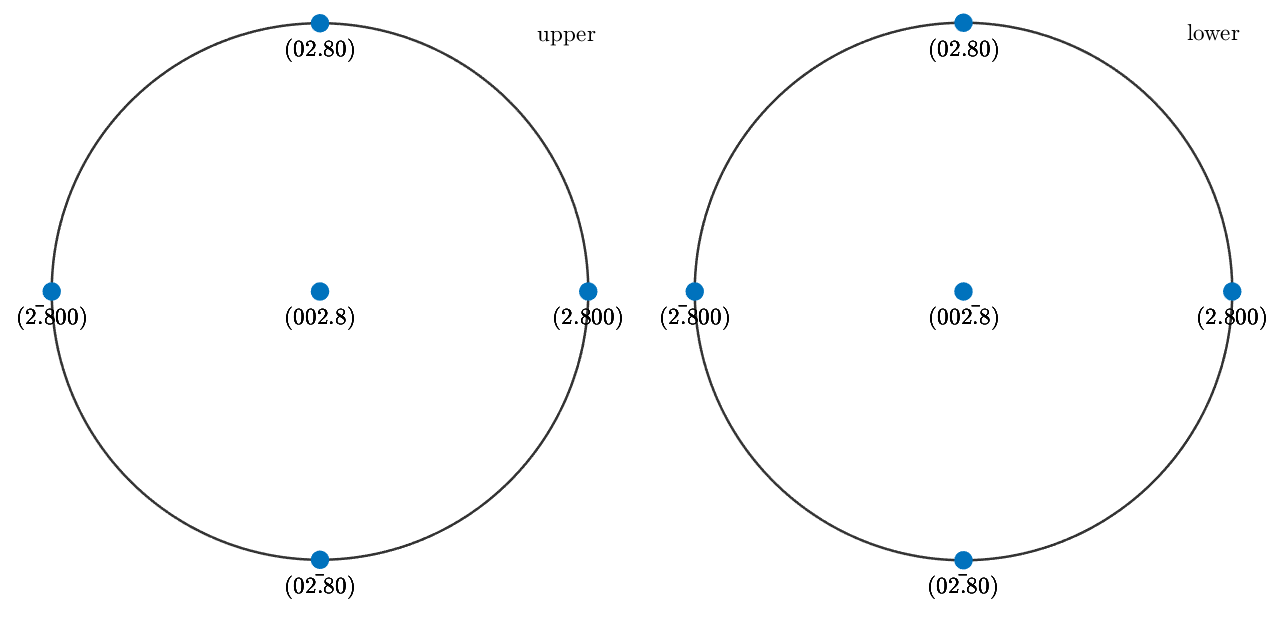


figure
l11=Miller(l1.x,l1.y,l1.z,crys_symm);
plot(l11.symmetrise,'labeled')


%%(200) pole figure
o=Miller(2,0,0,crys_symm);
o1=ori*o

 
o1 = vector3d
         x        y        z
  0.816497   1.1547  1.41421


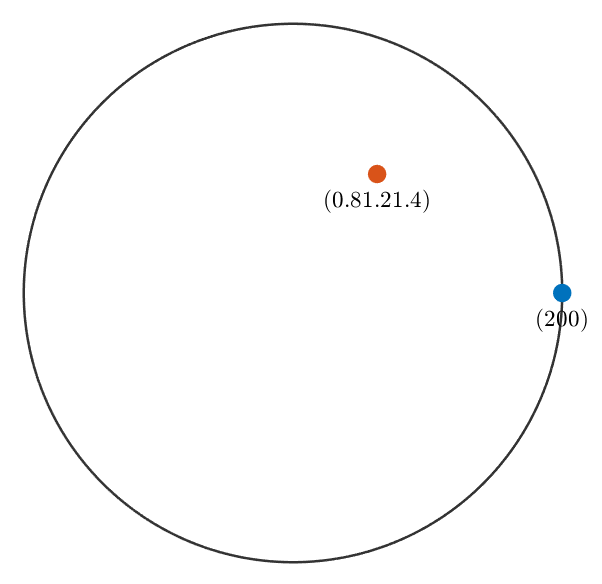


o11=Miller(o1.x,o1.y,o1.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(o,'upper','labeled')
hold on
plot(o11,'upper','labeled')
hold off

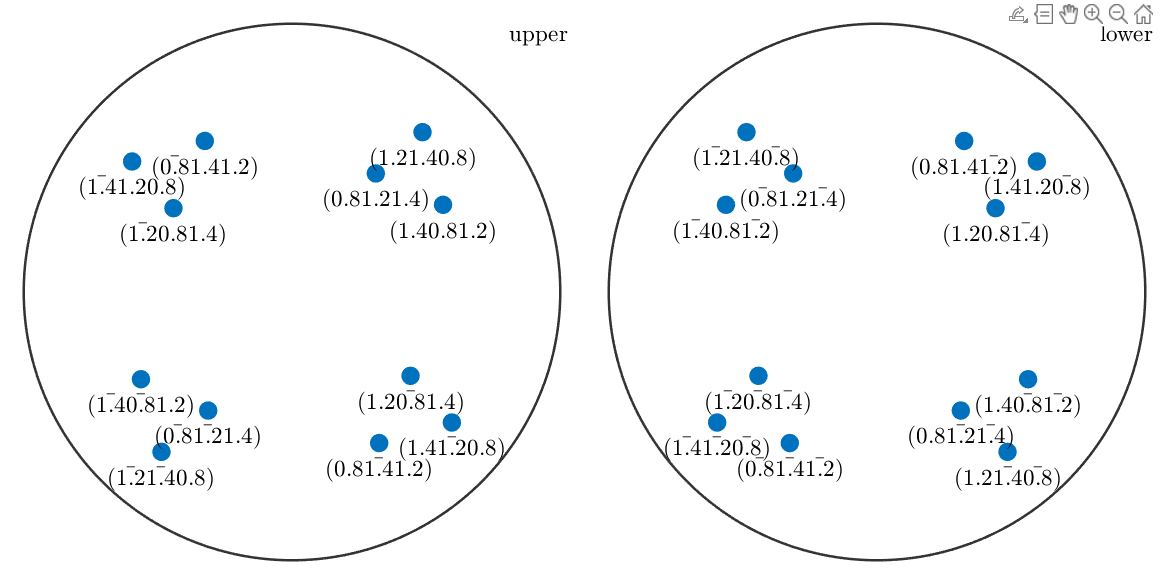


figure
o11=Miller(o1.x,o1.y,o1.z,crys_symm);
plot(o11.symmetrise,'labeled')

## 2. ORIENTATION B (110)[001]

crys_symm=crystalSymmetry('432');

## Define orientation using Miller indices

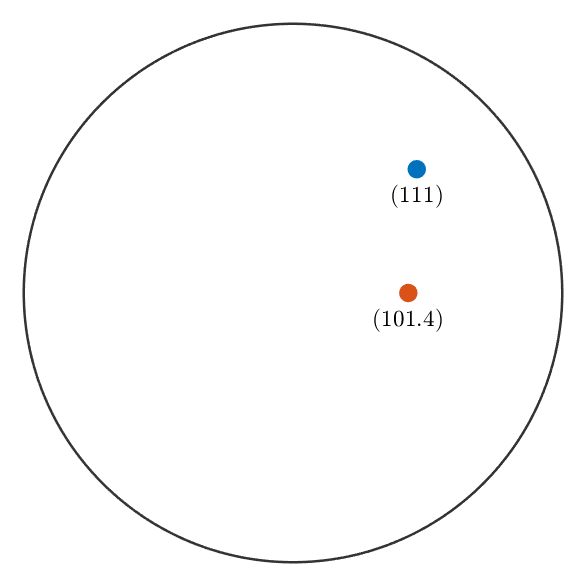

n1=Miller(1,1,0,'hkl',crys_symm); % plane normal || ND
b1=Miller(0,0,1,'uvw',crys_symm); % rolling direction || RD
ori1=orientation.byMiller(n1,b1);
%%(111) pole figure
m=Miller(1,1,1,crys_symm);
m2=ori1*m;
m21=Miller(m2.x,m2.y,m2.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(m,'upper','labeled')
hold on
plot(m21,'upper','labeled')
hold off

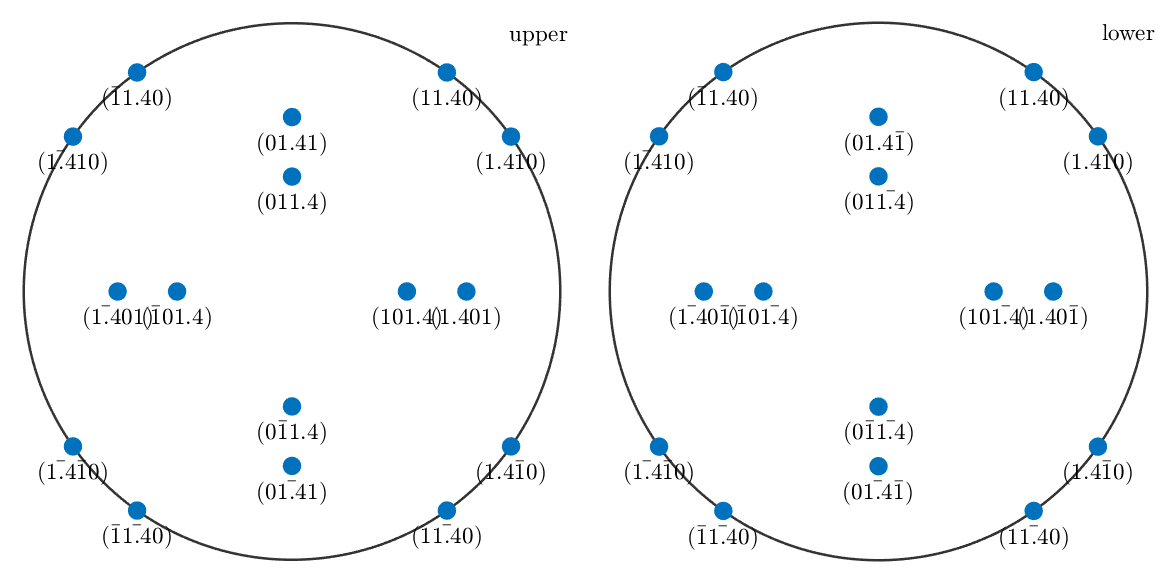


figure
m21=Miller(m2.x,m2.y,m2.z,crys_symm);
plot(m21.symmetrise,'labeled')


%%(220) pole figure
l=Miller(2,2,0,crys_symm);
l2=ori1*l;
l21=Miller(l2.x,l2.y,l2.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(l,'upper','labeled')
hold on
plot(l21,'upper','labeled')
hold off

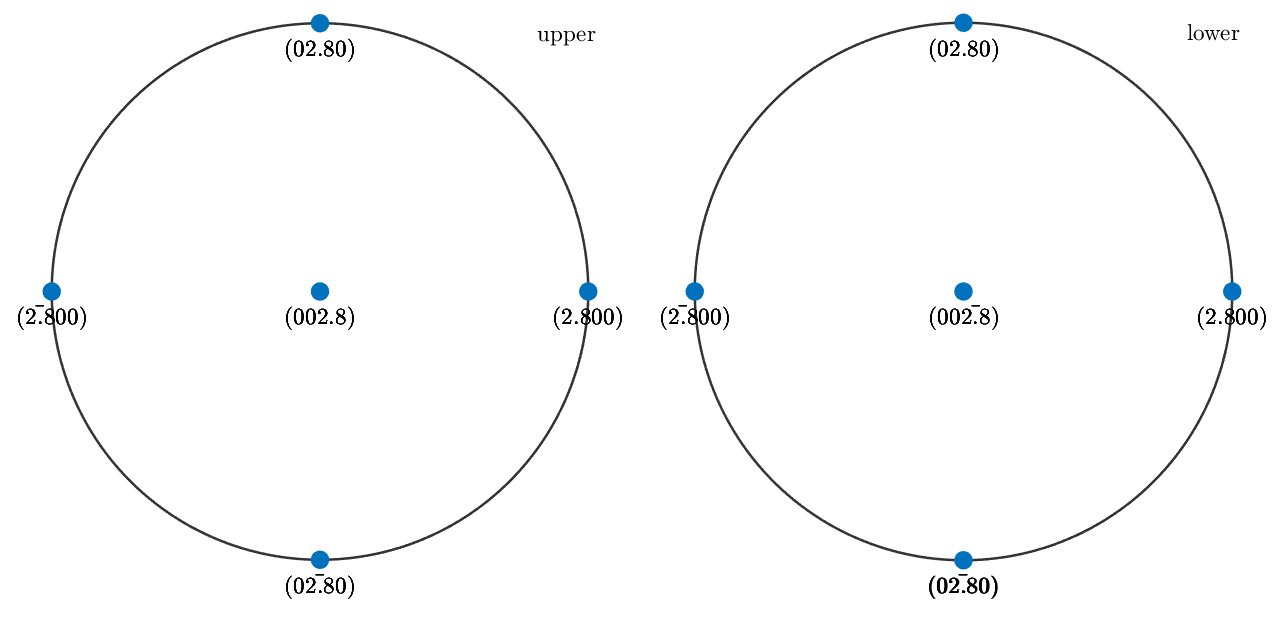


figure
l21=Miller(l2.x,l2.y,l2.z,crys_symm);
plot(l21.symmetrise,'labeled')


%%(200) pole figure
o=Miller(2,0,0,crys_symm);
o2=ori1*o

 
o2 = vector3d
  x       y       z
  0 1.41421 1.41421


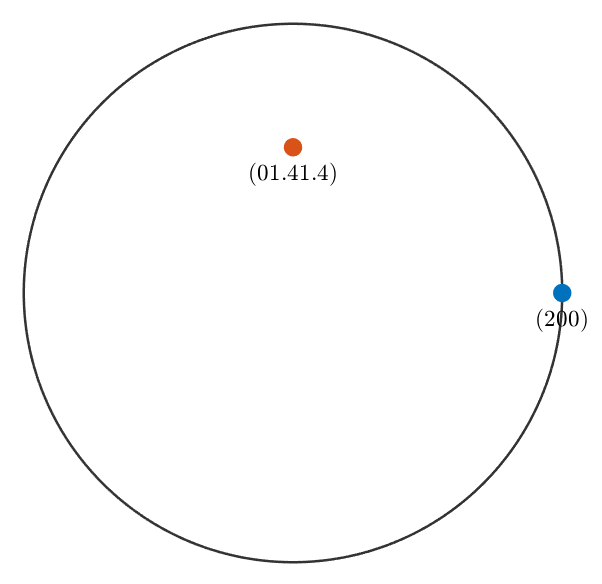


o21=Miller(o2.x,o2.y,o2.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(o,'upper','labeled')
hold on
plot(o21,'upper','labeled')
hold off

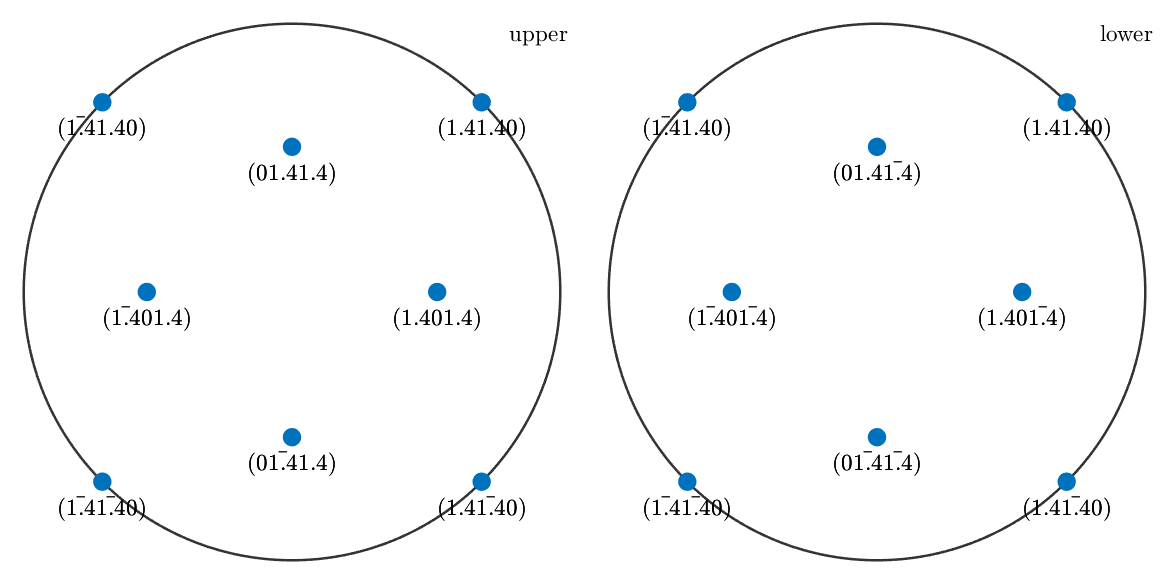


figure
o21=Miller(o2.x,o2.y,o2.z,crys_symm);
plot(o21.symmetrise,'labeled')

## 3. ORIENTATION C (634)[12-3]

crys_symm=crystalSymmetry('432');

## Define orientation using Miller indices

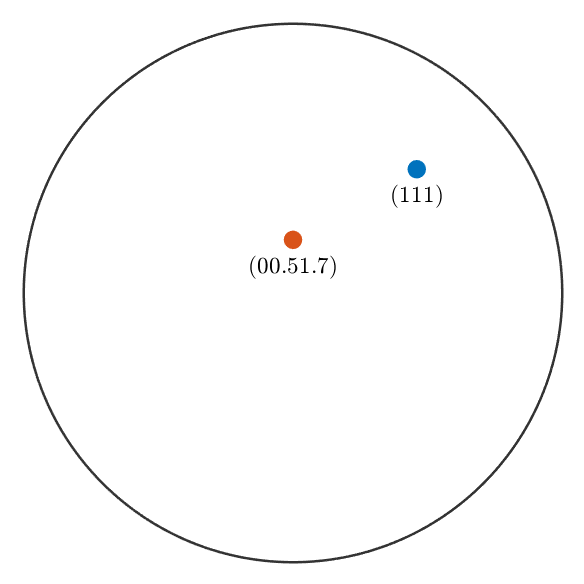

n2=Miller(6,3,4,'hkl',crys_symm); % plane normal || ND
b2=Miller(1,2,-3,'uvw',crys_symm); % rolling direction || RD
ori2=orientation.byMiller(n2,b2);
%%(111) pole figure
m=Miller(1,1,1,crys_symm);
m3=ori2*m;
m31=Miller(m3.x,m3.y,m3.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(m,'upper','labeled')
hold on
plot(m31,'upper','labeled')
hold off

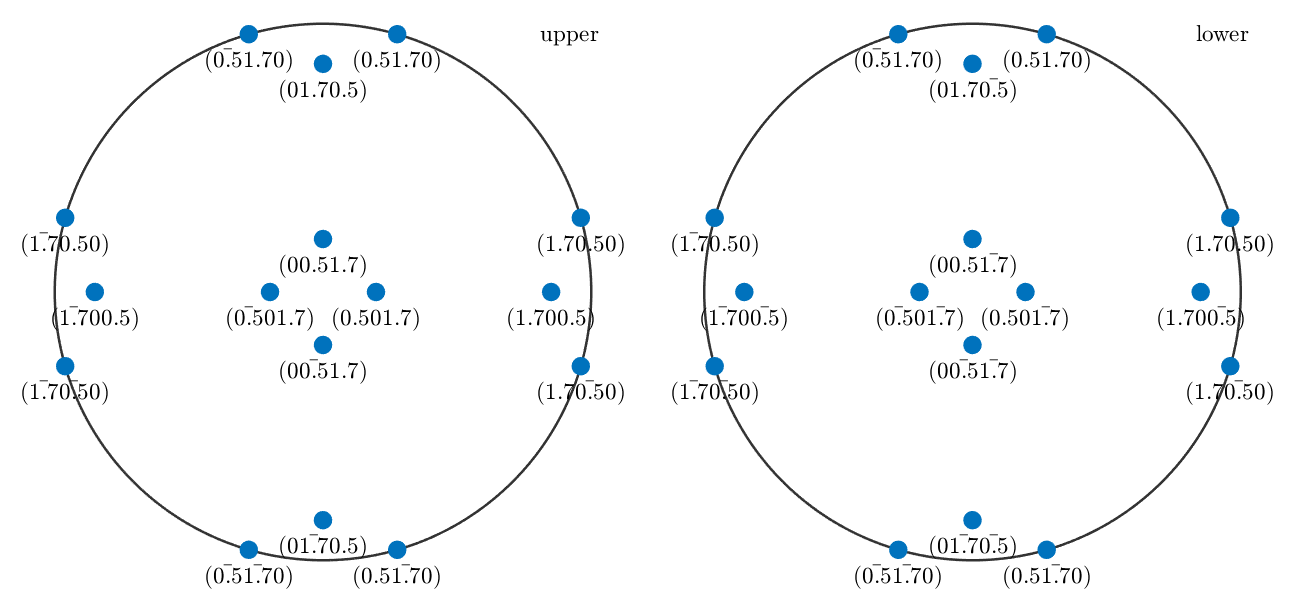


figure
m31=Miller(m3.x,m3.y,m3.z,crys_symm);
plot(m31.symmetrise,'labeled')

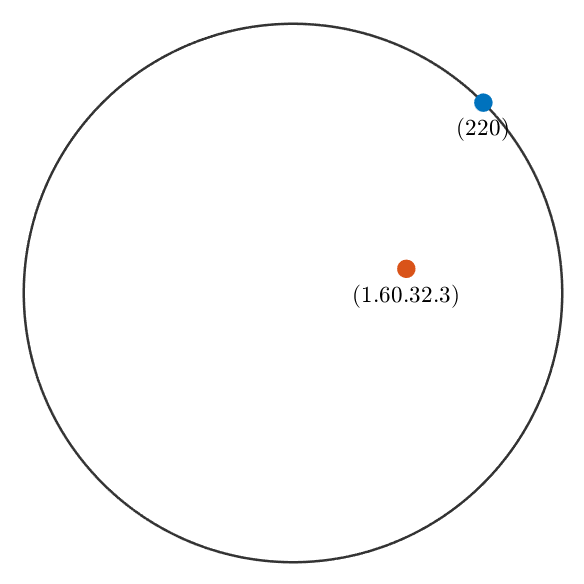


%%(220) pole figure
l=Miller(2,2,0,crys_symm);
l3=ori2*l;
l31=Miller(l3.x,l3.y,l3.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(l,'upper','labeled')
hold on
plot(l31,'upper','labeled')
hold off

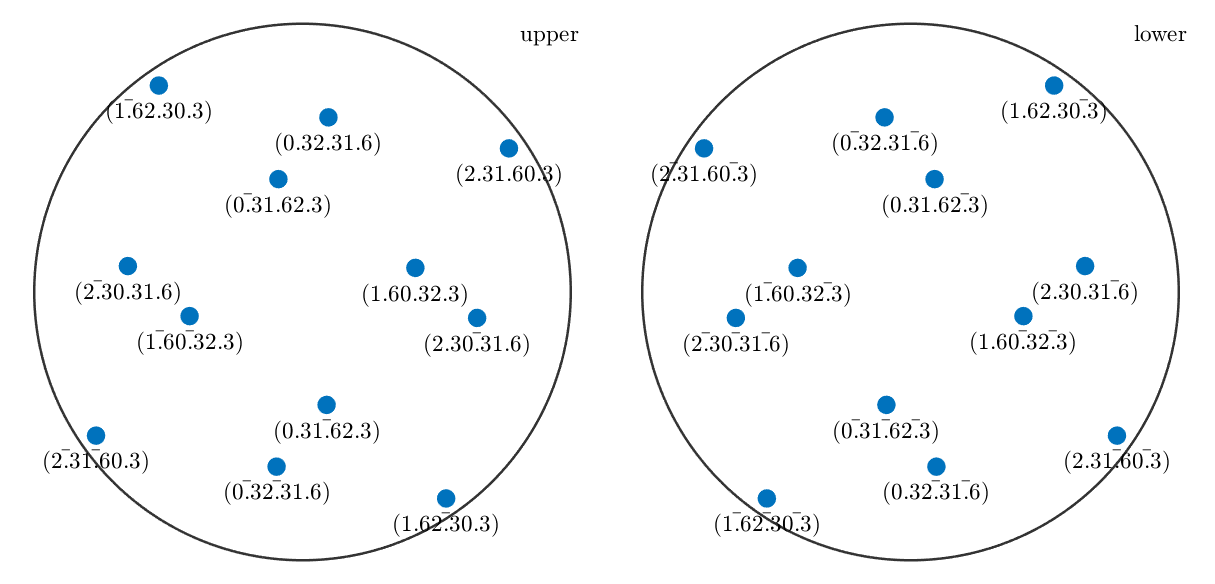


figure
l31=Miller(l3.x,l3.y,l3.z,crys_symm);
plot(l31.symmetrise,'labeled')


%%(200) pole figure
o=Miller(2,0,0,crys_symm);
o3=ori2*o

 
o3 = vector3d
         x        y        z
  0.534522 -1.16346  1.53644


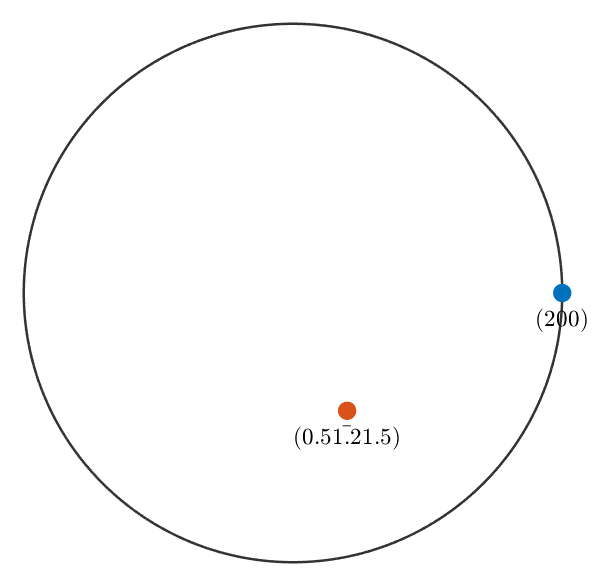


o31=Miller(o3.x,o3.y,o3.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(o,'upper','labeled')
hold on
plot(o31,'upper','labeled')
hold off

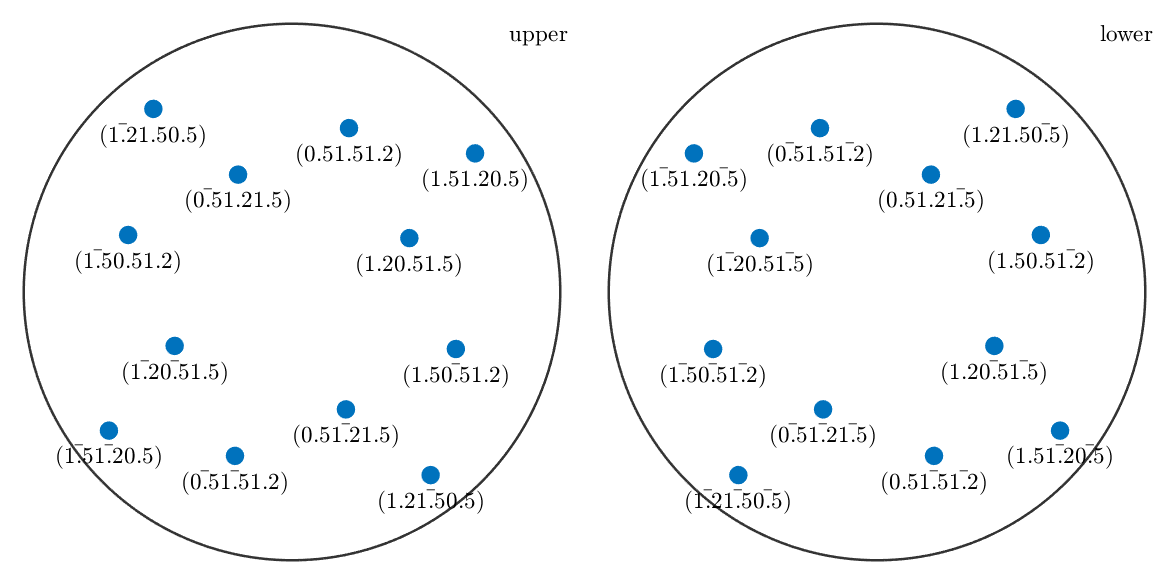


figure
o31=Miller(o3.x,o3.y,o3.z,crys_symm);
plot(o31.symmetrise,'labeled')

## 4. ORIENTATION D (001)[100]

crys_symm=crystalSymmetry('432');

## Defining orientation using Miller indices

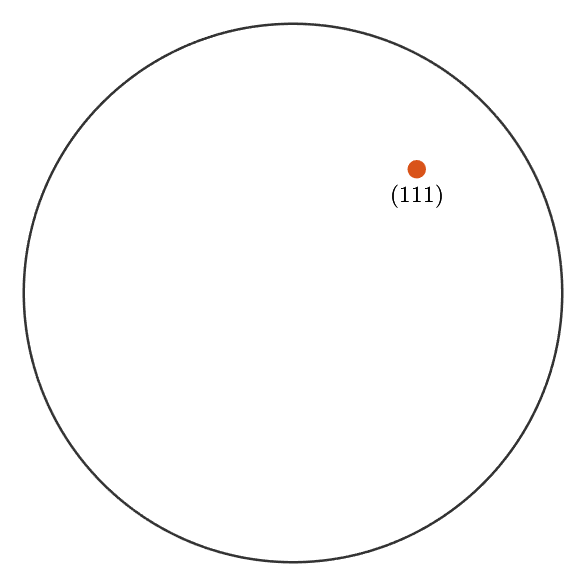

n3=Miller(0,0,1,'hkl',crys_symm); % plane normal || ND
b3=Miller(1,0,0,'uvw',crys_symm); % rolling direction || RD
ori3=orientation.byMiller(n3,b3);
%%(111) pole figure
m=Miller(1,1,1,crys_symm);
m4=ori3*m;
m41=Miller(m4.x,m4.y,m4.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(m,'upper','labeled')
hold on
plot(m41,'upper','labeled')
hold off

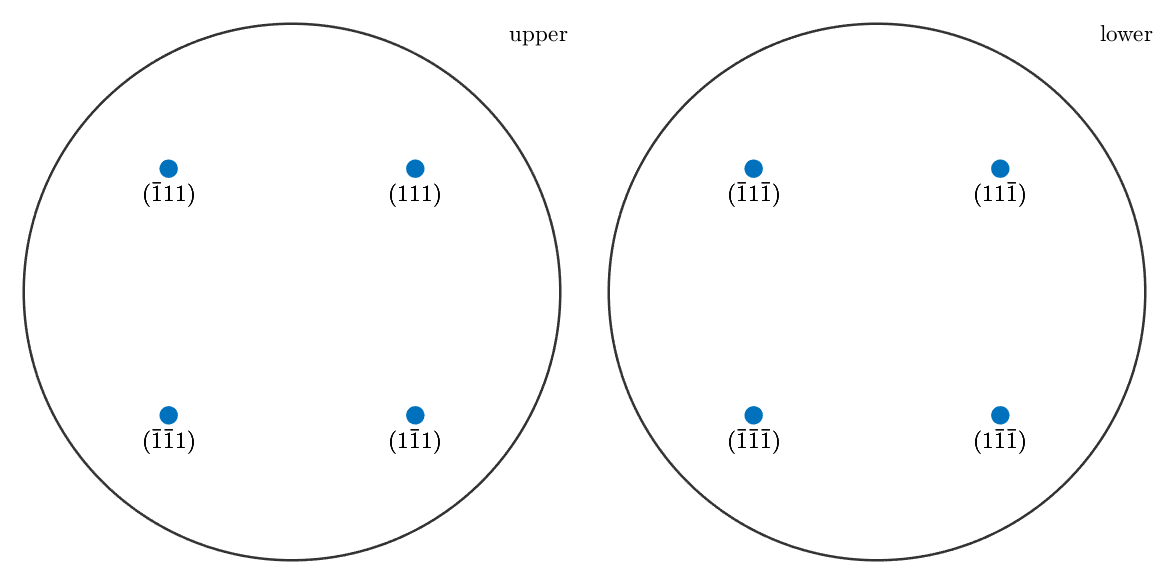


figure
m41=Miller(m4.x,m4.y,m4.z,crys_symm);
plot(m41.symmetrise,'labeled')

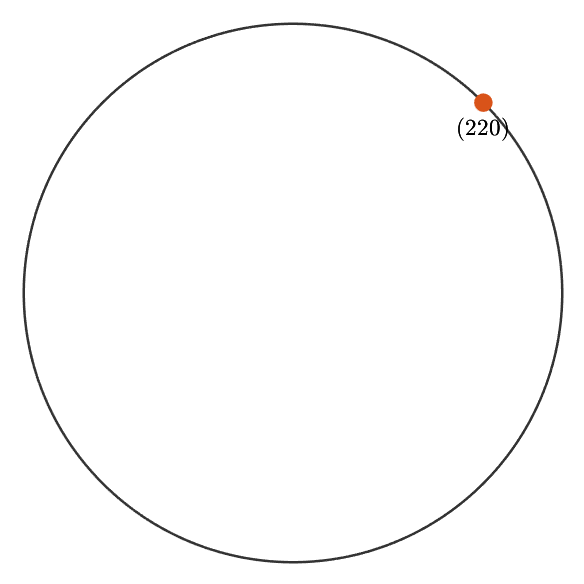


%%(220) pole figure
l=Miller(2,2,0,crys_symm);
l4=ori3*l;
l41=Miller(l4.x,l4.y,l4.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(l,'upper','labeled')
hold on
plot(l41,'upper','labeled')
hold off

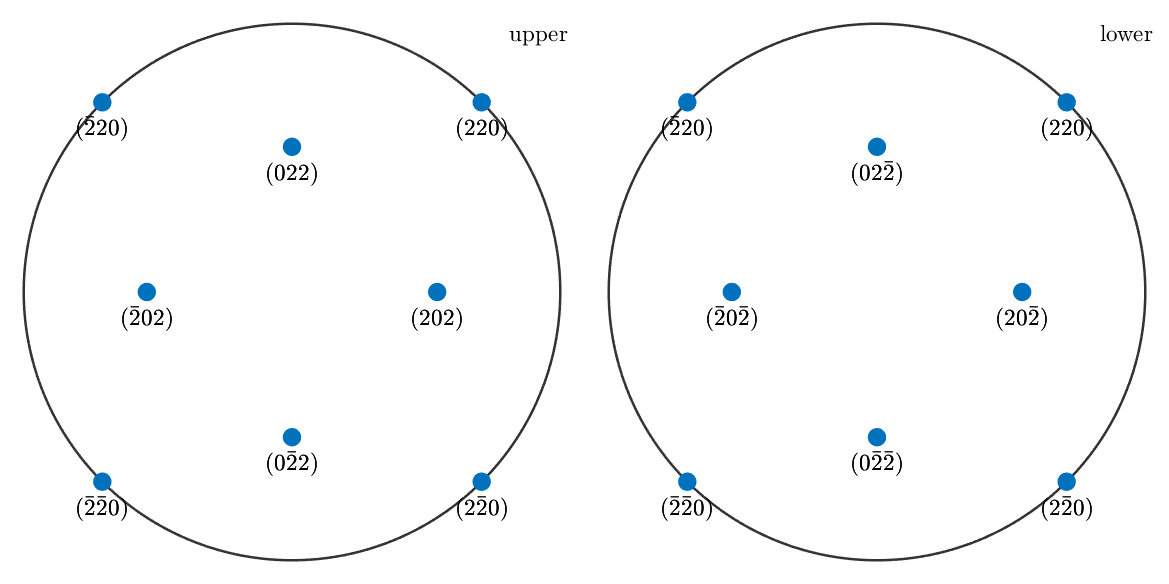


figure
l41=Miller(l4.x,l4.y,l4.z,crys_symm);
plot(l41.symmetrise,'labeled')


%%(200) pole figure
o=Miller(2,0,0,crys_symm);
o4=ori3*o

 
o4 = vector3d
  x y z
  2 0 0


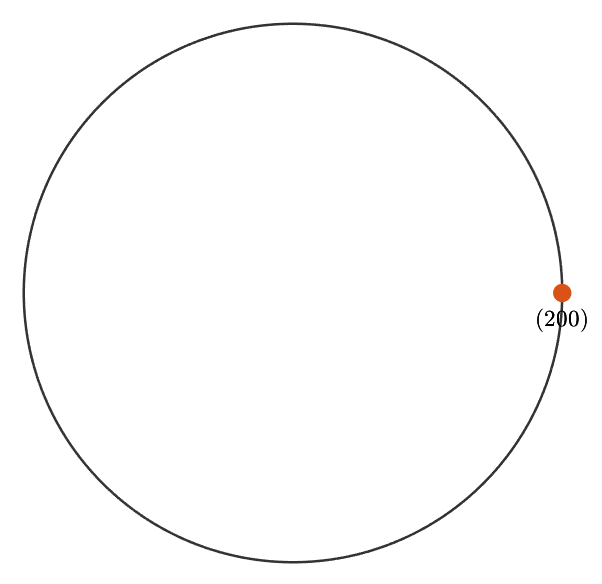


o41=Miller(o4.x,o4.y,o4.z,crys_symm);
%plotx2north
figure
% the normal direction
plot(o,'upper','labeled')
hold on
plot(o41,'upper','labeled')
hold off

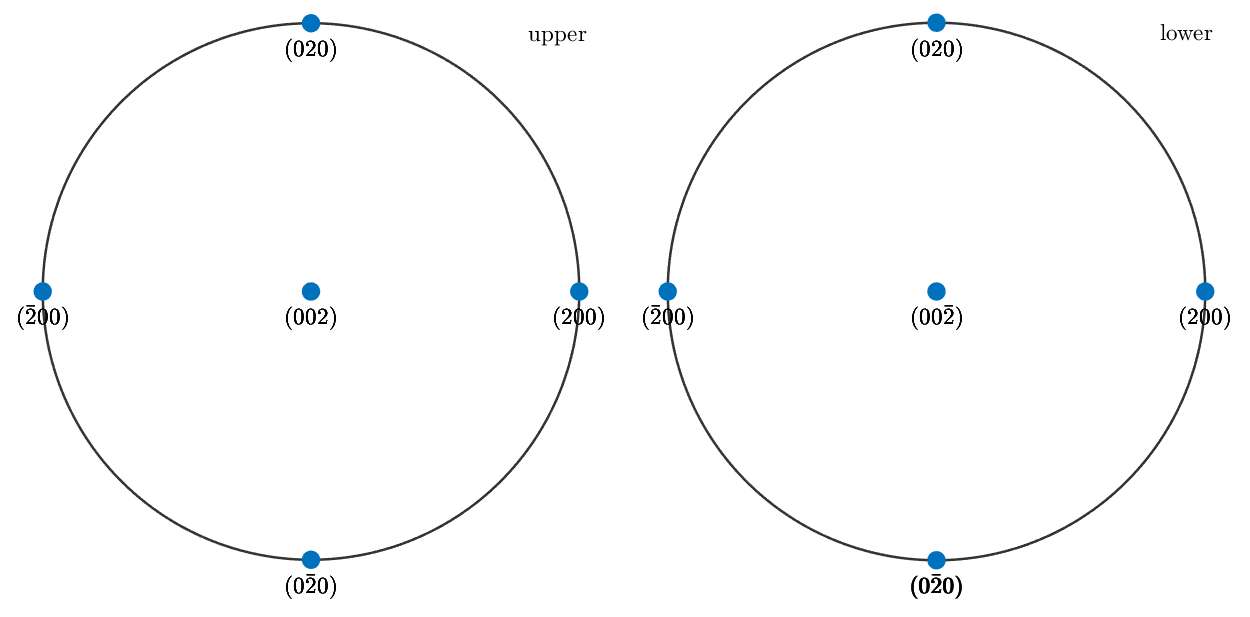


figure
o41=Miller(o4.x,o4.y,o4.z,crys_symm);
plot(o41.symmetrise,'labeled')